eeg_data = load("data/s20101m.mat");

eeg = eeg_data.val(1, :);

freq = 250;
M = 7;
lphf_output = lhpf(eeg, M);

nlpf_output = nlpf(lphf_output, freq);

qrs_peaks = dec(nlpf_output, freq);

fileID = fopen('qrs_peaks.asc', 'w');

for i = 1:numel(qrs_peaks)
    fprintf(fileID, '0:00:00.00 %d N 0 0 0\n', qrs_peaks(i));
end

fclose(fileID);

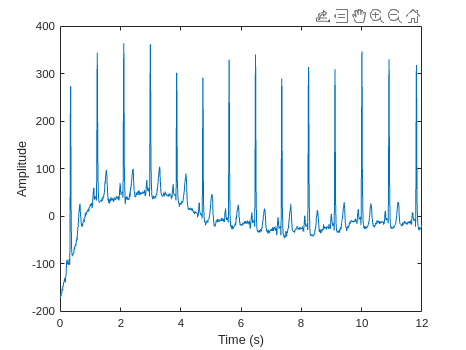

segment_length = 3000;
t = (0:segment_length-1) / freq;

figure;
plot(t(1:segment_length), eeg(1:segment_length));
hold on;

xlabel('Time (s)');
ylabel('Amplitude');

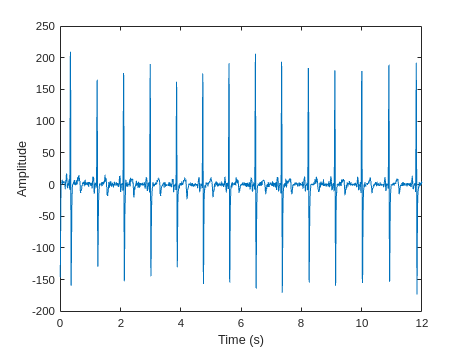


figure;
plot(t(1:segment_length), lphf_output(1:segment_length));
hold on;
xlabel('Time (s)');
ylabel('Amplitude');

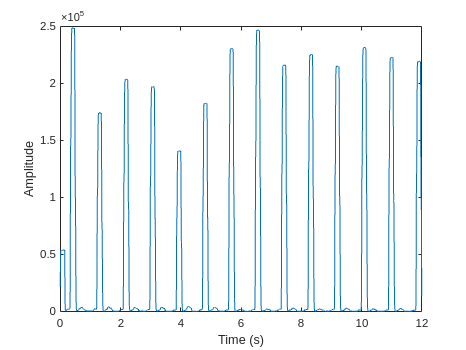


figure;
plot(t(1:segment_length), nlpf_output(1:segment_length));
hold on;
xlabel('Time (s)');
ylabel('Amplitude');

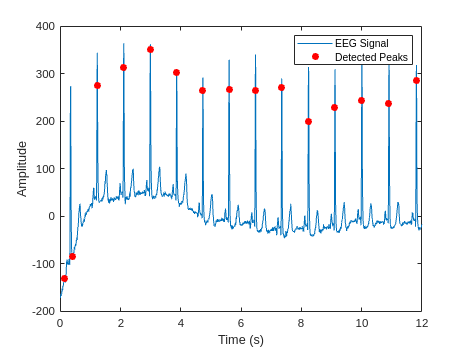


figure;
plot(t(1:segment_length), eeg(1:segment_length));
hold on;
scatter(qrs_peaks(qrs_peaks <= segment_length) / freq, eeg(qrs_peaks(qrs_peaks <= segment_length)), 'r', 'filled');
xlabel('Time (s)');
ylabel('Amplitude');
legend('EEG Signal', 'Detected Peaks');

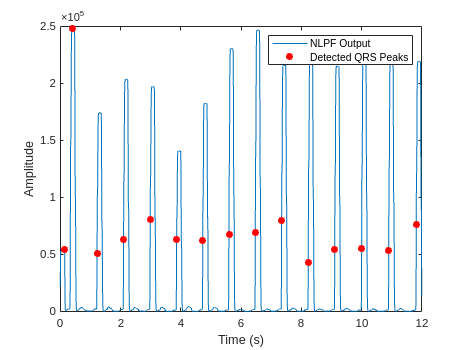



filtered_segment = nlpf_output(1:segment_length);

figure;
plot(t(1:segment_length), filtered_segment);
hold on;
scatter(qrs_peaks(qrs_peaks <= segment_length) / freq, filtered_segment(qrs_peaks(qrs_peaks <= segment_length)), 'r', 'filled');
xlabel('Time (s)');
ylabel('Amplitude');
legend('NLPF Output', 'Detected QRS Peaks');